%% Clear Workspace and Command Window
clear;  % Clears all variables from the workspace, ensuring no previous data is loaded
clc;    % Clears the command window to remove any previous output
disp("Workspace and command window cleared.");  % Display a message indicating that the workspace and command window have been cleared

Workspace and command window cleared.


%% Load Hyperspectral Data from .mat File
dataFile = 'f110712t01p00r18rdn_c_sc01_ort_img.mat';  % Define the name of the .mat file containing hyperspectral data
dataStruct = load(dataFile);  % Load the data from the .mat file into a structure named 'dataStruct'

% Display available fields in the loaded .mat file
disp('Fields in the loaded .mat file:');

Fields in the loaded .mat file:


disp(fieldnames(dataStruct));  % Display the names of all fields in the loaded .mat file

    {'Image'     }
    {'Wavelength'}



%% Create a Hypercube Object
% Dynamically identify the hyperspectral data field and wavelengths from the loaded data
fieldNames = fieldnames(dataStruct);  % Get the field names of the loaded data structure
bands = [];  % Initialize an empty variable to store the hyperspectral data (bands)
wavelengths = [];  % Initialize an empty variable to store the wavelength data

for i = 1:numel(fieldNames)
    fieldData = dataStruct.(fieldNames{i});  % Access the data for each field dynamically
    if ndims(fieldData) == 3  % Check if the data is 3-dimensional (hyperspectral data)
        bands = fieldData;  % Store the hyperspectral data (3D matrix)
    elseif isvector(fieldData) && isnumeric(fieldData)  % Check if the field contains wavelength data (1D array)
        wavelengths = fieldData;  % Store the wavelength data (1D array)
    end
end

% Create a hypercube object
hcube = hypercube(bands, wavelengths);  % Create a hypercube object using the hyperspectral bands and wavelengths
disp('Hypercube object created successfully:');  % Display a success message

Hypercube object created successfully:


disp(hcube);  % Display the details of the created hypercube object

  hypercube with properties:

      DataCube: "[4802x907x224 double]"
    Wavelength: [224×1 double]
      Metadata: [1×1 struct]




%% Remove Continuum and Calculate Spectral Indices
% Remove continuum from the hypercube data to normalize the reflectance values
normalizedData = removeContinuum(hcube);  % Call the 'removeContinuum' function to normalize the data

% Calculate spectral indices (e.g., NDVI, etc.) from the normalized data
spectralIndicesData = spectralIndices(normalizedData);  % Call the 'spectralIndices' function to calculate spectral indices

%% Identify CO₂ Absorption Bands
% Define the wavelength ranges for CO₂ absorption in NIR and SWIR regions (in nanometers)
co2_nir_range = [1570, 1610];  % Define the NIR CO₂ absorption range
co2_swir_range = [2000, 2060]; % Define the SWIR CO₂ absorption range

% Find the indices of the bands within the CO₂ absorption ranges
co2_nir_indices = find(hcube.Wavelength >= co2_nir_range(1) & hcube.Wavelength <= co2_nir_range(2));  % Find the NIR CO₂ band indices
co2_swir_indices = find(hcube.Wavelength >= co2_swir_range(1) & hcube.Wavelength <= co2_swir_range(2)); % Find the SWIR CO₂ band indices

% Display the indices of the CO₂ bands in the NIR and SWIR ranges
disp(['NIR CO₂ band indices: ', sprintf('%d ', co2_nir_indices)]);  % Display the indices of the NIR CO₂ bands

NIR CO₂ band indices: 129 130 131 132 


disp(['SWIR CO₂ band indices: ', sprintf('%d ', co2_swir_indices)]);  % Display the indices of the SWIR CO₂ bands

SWIR CO₂ band indices: 175 176 177 178 179 180 


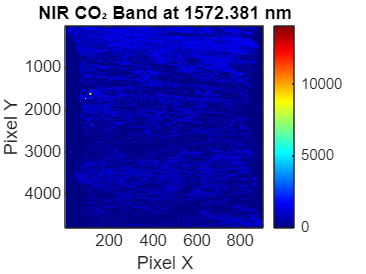

%% Extract and Visualize CO₂ Bands
% Visualize the first NIR CO₂ band if available
if ~isempty(co2_nir_indices)  % Check if there are any NIR CO₂ bands
    co2_nir_band = hcube.DataCube(:, :, co2_nir_indices(1));  % Extract the first NIR CO₂ band from the hypercube data
    figure;  % Create a new figure for displaying the band image
    imagesc(co2_nir_band);  % Display the NIR CO₂ band as an image (scale the values to fit the color range)
    colormap(jet);  % Use the 'jet' colormap to display the image in colorful shades
    colorbar;  % Add a color bar to the figure to indicate the intensity scale
    title(['NIR CO₂ Band at ', num2str(hcube.Wavelength(co2_nir_indices(1))), ' nm']);  % Set the title of the figure with the corresponding wavelength
    xlabel('Pixel X');  % Label the x-axis as 'Pixel X'
    ylabel('Pixel Y');  % Label the y-axis as 'Pixel Y'
end

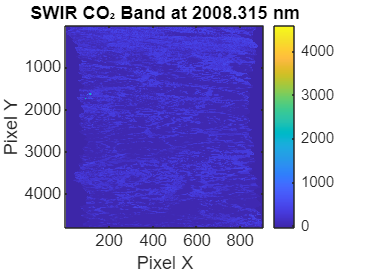


% Visualize the first SWIR CO₂ band if available
if ~isempty(co2_swir_indices)  % Check if there are any SWIR CO₂ bands
    co2_swir_band = hcube.DataCube(:, :, co2_swir_indices(1));  % Extract the first SWIR CO₂ band from the hypercube data
    figure;  % Create a new figure for displaying the band image
    imagesc(co2_swir_band);  % Display the SWIR CO₂ band as an image (scale the values to fit the color range)
    colormap(parula);  % Use the 'parula' colormap to display the image
    colorbar;  % Add a color bar to the figure to indicate the intensity scale
    title(['SWIR CO₂ Band at ', num2str(hcube.Wavelength(co2_swir_indices(1))), ' nm']);  % Set the title with the corresponding wavelength
    xlabel('Pixel X');  % Label the x-axis as 'Pixel X'
    ylabel('Pixel Y');  % Label the y-axis as 'Pixel Y'
end


% **Explanatory Notes for Visualization Section:**
% The images display the CO₂ absorption bands at specific wavelengths. 
% The NIR CO₂ band is shown first (around 1570-1610 nm), and the SWIR CO₂ band (around 2000-2060 nm) follows.
% These visualizations represent how the CO₂ concentration impacts the reflectance of light in those bands.
% Brighter areas typically indicate stronger absorption or higher CO₂ concentrations.

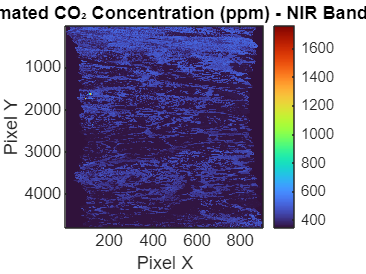


%% Estimate CO₂ Concentration
% Example calibration parameters for estimating CO₂ concentration from band data
scalingFactor = 0.1;  % Scaling factor to convert band reflectance values to CO₂ concentration
offset = 350;         % Baseline CO₂ concentration in ppm (parts per million)

% Convert the NIR CO₂ band to CO₂ concentration in ppm
if exist('co2_nir_band', 'var')  % Check if the NIR CO₂ band exists
    co2_nir_ppm = co2_nir_band * scalingFactor + offset;  % Convert NIR band values to CO₂ concentration in ppm
    figure;  % Create a new figure for displaying the CO₂ concentration map
    imagesc(co2_nir_ppm);  % Display the CO₂ concentration map as an image
    colormap(turbo);  % Use the 'turbo' colormap for better visual clarity of concentration variations
    colorbar;  % Add a color bar to the figure for interpreting the CO₂ concentration scale
    title('Estimated CO₂ Concentration (ppm) - NIR Band');  % Set the title of the figure
    xlabel('Pixel X');  % Label the x-axis as 'Pixel X'
    ylabel('Pixel Y');  % Label the y-axis as 'Pixel Y'
end

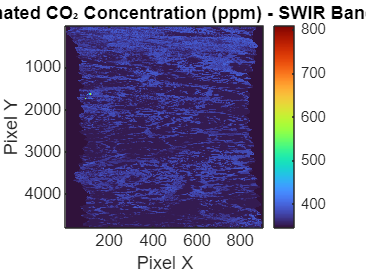


% Convert the SWIR CO₂ band to CO₂ concentration in ppm
if exist('co2_swir_band', 'var')  % Check if the SWIR CO₂ band exists
    co2_swir_ppm = co2_swir_band * scalingFactor + offset;  % Convert SWIR band values to CO₂ concentration in ppm
    figure;  % Create a new figure for displaying the CO₂ concentration map
    imagesc(co2_swir_ppm);  % Display the CO₂ concentration map as an image
    colormap(turbo);  % Use the 'turbo' colormap for clarity
    colorbar;  % Add a color bar to the figure
    title('Estimated CO₂ Concentration (ppm) - SWIR Band');  % Set the title of the figure
    xlabel('Pixel X');  % Label the x-axis as 'Pixel X'
    ylabel('Pixel Y');  % Label the y-axis as 'Pixel Y'
end


% Explanatory Notes for CO₂ Concentration Estimation:**
% The CO₂ concentration maps display the estimated concentration values based on the NIR and SWIR bands.
% The scaling factor and offset are used to convert the reflectance values from the hyperspectral data into CO₂ concentration values in ppm.
% Higher intensity or brighter areas typically correspond to higher CO₂ concentrations in the image.

%% Save CO₂ Band Images (Optional)
% Optionally, save the extracted CO₂ band images for later use or analysis
if exist('co2_nir_band', 'var')  % Check if the NIR CO₂ band exists
    outputNirFile = 'co2_nir_band_image.mat';  % Define the output file name for the NIR band image
    save(outputNirFile, 'co2_nir_band');  % Save the NIR CO₂ band to the .mat file
    disp(['NIR CO₂ band image saved to ', outputNirFile]);  % Display a message indicating the file has been saved
end

NIR CO₂ band image saved to co2_nir_band_image.mat



if exist('co2_swir_band', 'var')  % Check if the SWIR CO₂ band exists
    outputSwirFile = 'co2_swir_band_image.mat';  % Define the output file name for the SWIR band image
    save(outputSwirFile, 'co2_swir_band');  % Save the SWIR CO₂ band to the .mat file
    disp(['SWIR CO₂ band image saved to ', outputSwirFile]);  % Display a message indicating the file has been saved
end

SWIR CO₂ band image saved to co2_swir_band_image.mat



disp('Processing complete.');  % Display a message indicating the processing is complete

Processing complete.



%% Function to Switch Matching Algorithms
% Define a function to switch between different spectral matching algorithms
function result = matchAlgorithm(data, algorithmType)
    switch algorithmType
        case 'matchedFilter'
            result = spectralMatch(data, 'matchedFilter');  % Use spectralMatch for matched filter
        case 'anotherAlgorithm'
            result = spectralMatch(data, 'anotherAlgorithm');  % Placeholder for another algorithm
        otherwise
            error('Unknown algorithm type specified.');  % Raise an error if an unknown algorithm is provided
    end
end
